% clear all 
% close all
path='Z:\archivedwl-528\Second report\partie2\Exercise 5\';
%------------------constants----------------------------------------------
N=100;
r=1e-9;
c=1;
a=5*r;
eV=1.60217656535e-19;
hbar=1.05457172647e-34;
mel=9.10938291e-31;
V0=-1.5*eV;
dx=a/(N+1);
%-------------------------------------------------------------------------

%-------------------------------------V(x)--------------------------------
V=zeros(N^2);
x=@(i) mod(i,N)*dx-dx*N/2; % gives x coordinate with vector index i (assumes (0,0) coordinate is in the midle)
y=@(i) ceil(i/N)*dx-dx*N/2; %y coordinate from i
for i=1:N^2 
    if (y(i)/c)^2+x(i)^2<r^2
        V(i,i)=V0;
    end
end
%-----------------test
% test=(diag(V)<0);
% for i=1:N
%     test_(i,1:N)=test((i-1)*N+1:i*N);
% end
% pcolor(test_)
%---------------------
%-------------------------------------------------------------------------

% ------------------------delta-------------------------------------------
delta=zeros(N^2);
for i=1:N^2
    delta(i,i)=-4;
    if i+1<=N^2 && floor((i-1)/N)==floor((i+1-1)/N)
        delta(i,i+1)=1;
    end
    if i-1>0 && floor((i-1)/N)==floor((i-1-1)/N)
        delta(i,i-1)=1;
    end
    if i+N<=N^2
        delta(i,i+N)=1;
    end
    if i-N>0
        delta(i,i-N)=1;
    end
end
delta=delta/dx^2;
%--------------------------------------------------------------------------

%------------construction of H (hamiltonian)-------------------------------
H_=-hbar^2/2/mel*delta + V;
H=sparse(-hbar^2/2/mel*delta + V);
%--------------------------------------------------------------------------

%1) look for number of bound solutions

E=eigs(H,15,V0)/eV;
temp=E<0;
num_bound=sum(temp)

num_bound = 10

% ------- three lowest energy eigenvalue and eigenvector
[vec,E_c1]=eigs(H,3,V0);
diag(E_c1/eV) % in eV

ans =    -1.3371
   -1.0900
   -1.0900


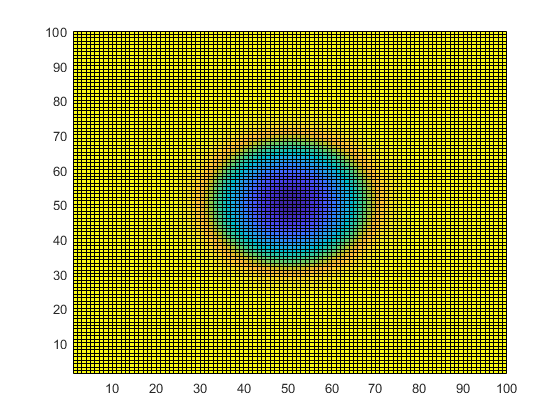


%-----------eigenfunction & proba density
psi1=zeros(N);
psi2=zeros(N);
psi3=zeros(N);
for i=1:N
    psi1(i,1:N)=vec((i-1)*N+1:i*N,1);
    psi2(i,1:N)=vec((i-1)*N+1:i*N,2);
    psi3(i,1:N)=vec((i-1)*N+1:i*N,3);
end
pdf1=psi1.^2;
pdf2=psi2.^2;
pdf3=psi3.^2;

pcolor(psi1);
saveas(gcf,strcat(path,'psi1'),'png');

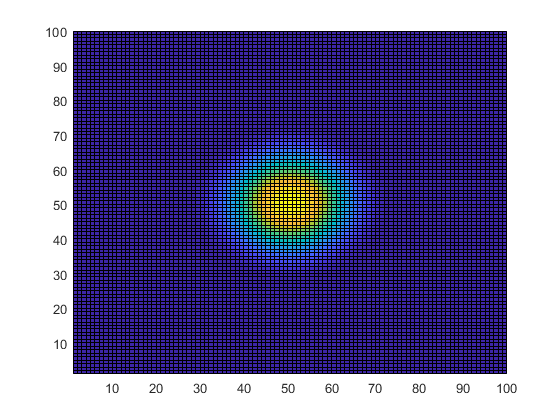

pcolor(pdf1);
saveas(gcf,strcat(path,'pdf1'),'png');

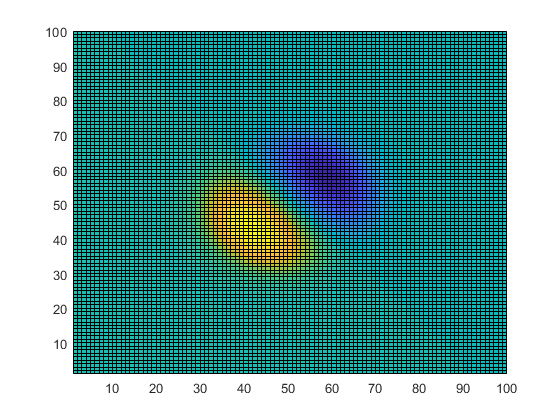

pcolor(psi2);
saveas(gcf,strcat(path,'psi2'),'png');

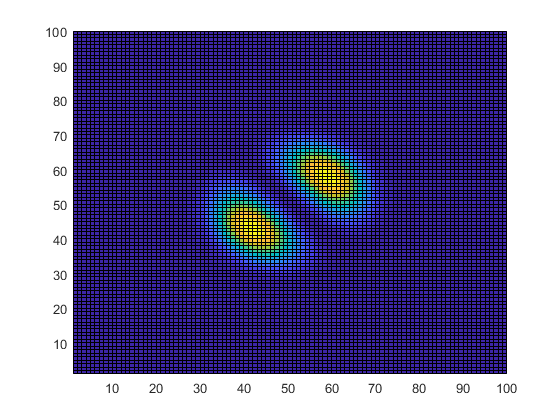

pcolor(pdf2);
saveas(gcf,strcat(path,'pdf2'),'png');

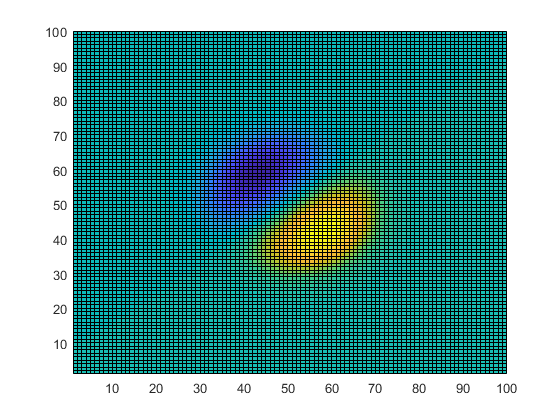

pcolor(psi3);
saveas(gcf,strcat(path,'psi3'),'png');

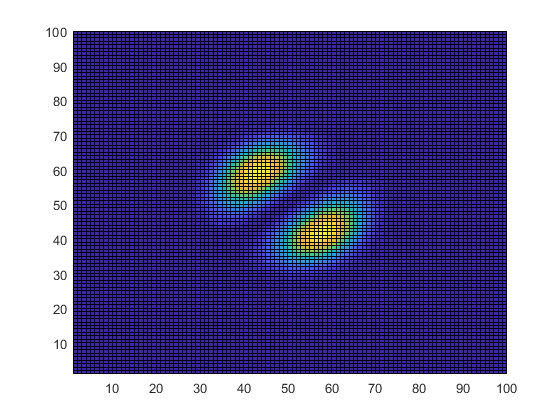

pcolor(pdf3);
saveas(gcf,strcat(path,'pdf3'),'png');

% question 2
[vecscat,Escat]=eigs(H,1,1*eV);
Escat/eV

ans = 1.0034

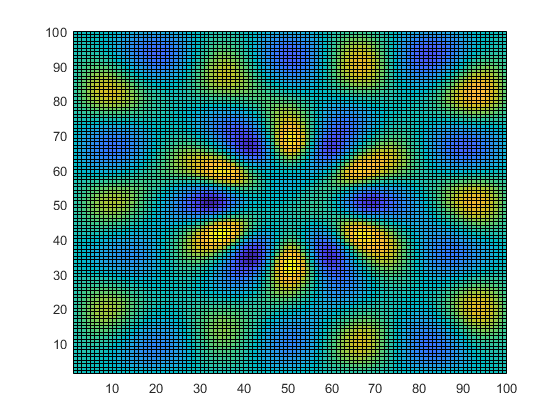

forfilter=(diag(V)<0);
psi=zeros(N);
filter=zeros(N);
for i=1:N
    psi(i,1:N)=vecscat((i-1)*N+1:i*N);
    filter(i,1:N)=forfilter((i-1)*N+1:i*N);
end
pdf=psi.^2;

pcolor(psi);
saveas(gcf,strcat(path,'psi'),'png');

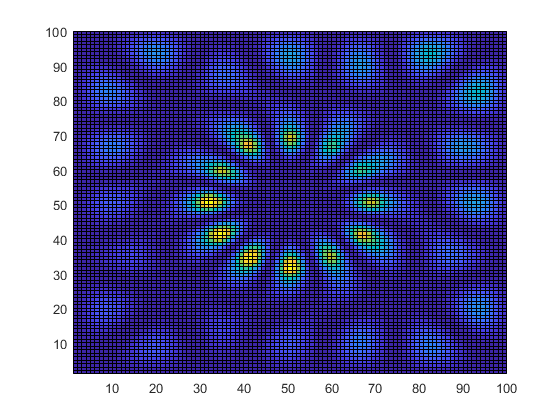

pcolor(pdf);
saveas(gcf,strcat(path,'pdf'),'png');

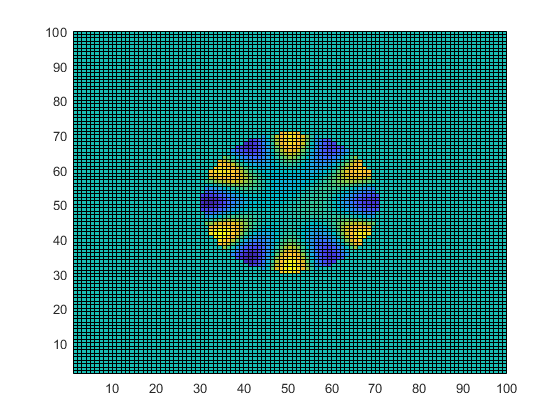

pcolor(psi.*filter);

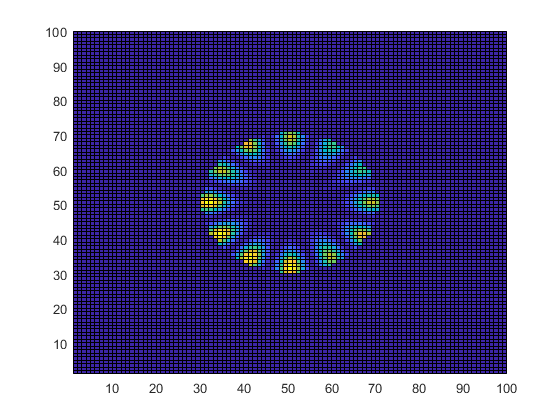

pcolor(pdf.*filter)

proba=trapz(dx,trapz(dx,filter.*pdf,2))/trapz(dx,trapz(dx,pdf,2))

proba = 0.2700

proba1=trapz(dx,trapz(dx,filter.*pdf1,2))/trapz(dx,trapz(dx,pdf1,2))

proba1 = 0.9843

proba2=trapz(dx,trapz(dx,filter.*pdf2,2))/trapz(dx,trapz(dx,pdf2,2))

proba2 = 0.9575

proba3=trapz(dx,trapz(dx,filter.*pdf3,2))/trapz(dx,trapz(dx,pdf3,2))

proba3 = 0.9575

% question 3
num=50; %50
c=linspace(1,15,num);
boundnum=ones(1,num);
for i=1:num
    index=15;
    H=ham(c(i));
    maxenergy=V0;
    while maxenergy<0 
        E=eigs(H,index,V0);
        maxenergy=max(max(E(:)));
        index=index+10;
    end
    boundnum(i)=sum(E<0);
end

'ham' is not found in the current folder or on the MATLAB path, but exists in:
    Z:\archivedwl-528\Second report\partie2\Exercise 5

Change the MATLAB current folder or add its folder to the MATLAB path.

%exercise 3 following
boundnum
plot(c,boundnum,'*-')
xlabel('c$\mathrm{[\,]}$','Interpreter','latex','FontSize',18);
ylabel('number of bound states $\mathrm{[\,]}$','Interpreter','latex','FontSize',18);
set(gca,'FontSize',14)
saveas(gcf,strcat(path,'numboundstatesasfuncofc'),'png');

%question 4

diag(E_c1/eV)


c=25;
H=ham(c);
[vec,E_c25]=eigs(H,3,V0);
diag(E_c25/eV)
psi1_c25=zeros(N);
psi2_c25=zeros(N);
psi3_c25=zeros(N);
for i=1:N
    psi1_c25(i,1:N)=vec((i-1)*N+1:i*N,1);
    psi2_c25(i,1:N)=vec((i-1)*N+1:i*N,2);
    psi3_c25(i,1:N)=vec((i-1)*N+1:i*N,3);
end
pdf1_c25=psi1_c25.^2;
pdf2_c25=psi2_c25.^2;
pdf3_c25=psi3_c25.^2;
pcolor(psi1)
pcolor(psi1_c25)
saveas(gcf,strcat(path,'psi1_c25'),'png');
pcolor(psi2)
pcolor(psi2_c25)
saveas(gcf,strcat(path,'psi2_c25'),'png');
pcolor(psi3)
pcolor(psi3_c25)
saveas(gcf,strcat(path,'psi3_c25'),'png');
pcolor(pdf1)
pcolor(pdf1_c25)
saveas(gcf,strcat(path,'pdf1_c25'),'png');
pcolor(pdf2)
pcolor(pdf2_c25)
saveas(gcf,strcat(path,'pdf2_c25'),'png');
pcolor(pdf3)
pcolor(pdf3_c25)
saveas(gcf,strcat(path,'pdf3_c25'),'png');